## Parameters and Equilibrium Conditions

P4 = [2 1 1 1 0.5 1];
E1 = [0 0 0];
E2 = [0 pi pi];
case7 = num2cell([P4,E1]);
case8 = num2cell([P4,E2]);


C = [1 0 0 0 0 0]; 
D = 0;
tmax = 100;

## Case 7: P4, E1

[m0, m1, m2, l1, l2, g, ye, theta1e, theta2e] = deal(case7{:});
mt = m0 + m1 + m2;
M = [mt, -m1*l1*cos(theta1e), -m2*l2*cos(theta2e);
    -m1*l1*cos(theta1e), m1*l1^2, 0;
    -m2*l2*cos(theta2e), 0, m2*l2^2];
G = [0,0,0;0,m1*l1*g*cos(theta1e),0;0,0,m2*l2*g*cos(theta2e)];
Q = [1 0 0]';
k = 0.5

k = 0.5000

c = 5

c = 5

K = [-k 0 0; 0 0 0; 0 0 0] + (-G); 
Z = [-c 0 0; 0 0 0; 0 0 0];
A = [zeros(3), eye(3); M^-1*K, M^-1*Z]

A =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
   -0.2500   -0.5000   -0.5000   -2.5000         0         0
    0.2500    1.5000    0.5000    2.5000         0         0
    0.5000    1.0000    3.0000    5.0000         0         0


B = [zeros(3,1); M^-1*Q]

B =          0
         0
         0
    0.5000
   -0.5000
   -1.0000


[p,z] = pzmap(ss(A,B,C,D))

p =    -3.0258
   -1.2168
   -0.7563
   -0.1097
    1.5570
    1.0516


z =    -1.4142
   -1.0000
    1.4142
    1.0000


omega = abs(max(z))

omega = 1.4142

% omega = 6
IC  = [0 0 0 0 0 0]'

IC =          0
    3.1416
    3.1416
         0
         0
         0


% IC = rand(6,1)
t = linspace(0,tmax,2^12);
[t,x] = ode45(@(t,x) xfun(x,A,B,omega,t),t,IC); % linear
[t,x2] = ode45(@(t,x) xfun2(x, m0, m1, m2, l1, l2, g, mt, c,k, omega,t),t,IC); % nonlinear
figure
plot(t,x(:,1))
hold on
plot(t,x2(:,1),'--')
title('Cart Position (y)')
xlabel('Time [s]')
ylabel('Cart Position [m]')
legend('Linearized','Nonlinear','Location',"best")

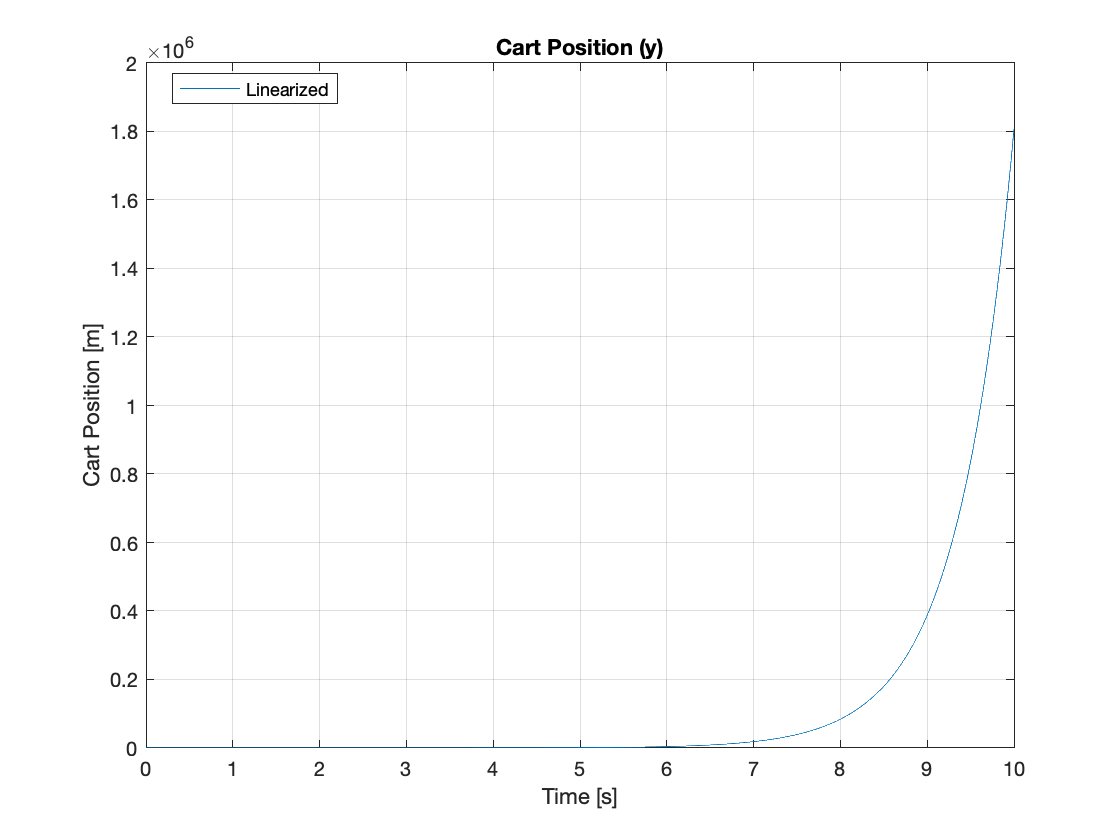

grid on

## Linearized

function dxdt = xfun(x,A,B,omega,t)
w = sin(omega*t);
dxdt = A*x + B.*w;
end

## Nonlinear

function dxdt = xfun2(x, m0, m1, m2, l1, l2, g, mt, c, k, omega, t)
u = -k*x(1) - c*x(4) + sin(omega*t);
% u = 0;
M = [mt, -m1*l1*cos(x(2)), -m2*l2*cos(x(3));
    -m1*l1*cos(x(2)), m1*l1^2, 0;
    -m2*l2*cos(x(3)), 0, m2*l2^2];
G = [m1*l1*sin(x(2))*x(5)^2 + m2*l2*sin(x(3))*x(6)^2;
    m1*l1*g*sin(x(2));
    m2*l2*g*sin(x(3))];
W = [1;0;0];
q = x(1:3);
qdot = x(4:6);
qddot = M^-1*(W*u-G);
dxdt = [qdot; qddot];
end